### This file calls pairsNew.m, which is where the main trading strategy is located. Runnning this should give trading results. 

clear
clc
load SPX218.mat
load SPX218industry.mat
load coStocks.mat

% For in-sample set
startDate = datetime('1/1/1990','InputFormat','MM/dd/uuuu');
endDate = datetime('12/31/1996','InputFormat','MM/dd/uuuu');
% For out-of-sample set
% startDate = datetime('1/1/1994','InputFormat','MM/dd/uuuu');
% endDate = datetime('12/31/2000','InputFormat','MM/dd/uuuu');
SPX218 = SPX218(SPX218.Date >= startDate & SPX218.Date <= endDate, :);

[numDays, numStocks] = size(SPX218);
numStocks = numStocks - 1;

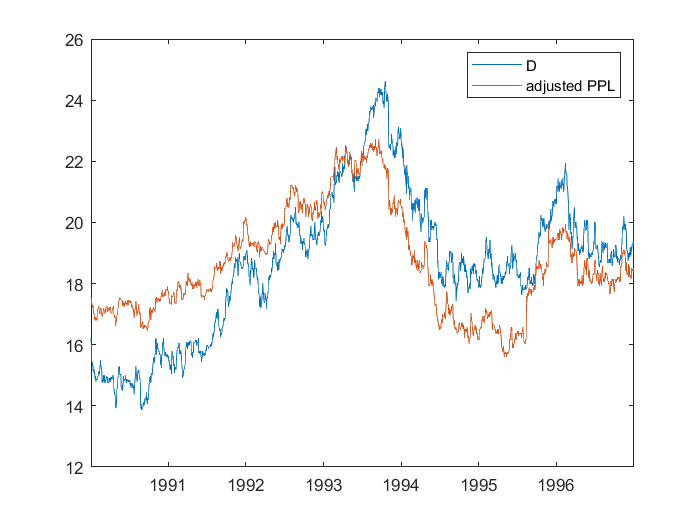

outliers = 3;
%Stock1 = cell2mat(coStocks(outliers + 1,2));
%Stock2 = cell2mat(coStocks(outliers + 1,3));
Stock1 = 54;
Stock2 = 173;
series = [SPX218{:, Stock1+1} SPX218{:, Stock2+1}];
[h,pValue,stat,~,reg0] = egcitest(series);
x = (1:numDays)';
clf
plot(SPX218{:,1}, series(:,1))
hold on
plot(SPX218{:,1}, (series(:,2)*reg0.coeff(2)+reg0.coeff(1)))
Stock1Name = cell2mat(SPX218(:,Stock1+1).Properties.VariableNames);
Stock2Name = cell2mat(SPX218(:,Stock2+1).Properties.VariableNames);
legend(Stock1Name, "adjusted " +Stock2Name);
hold off

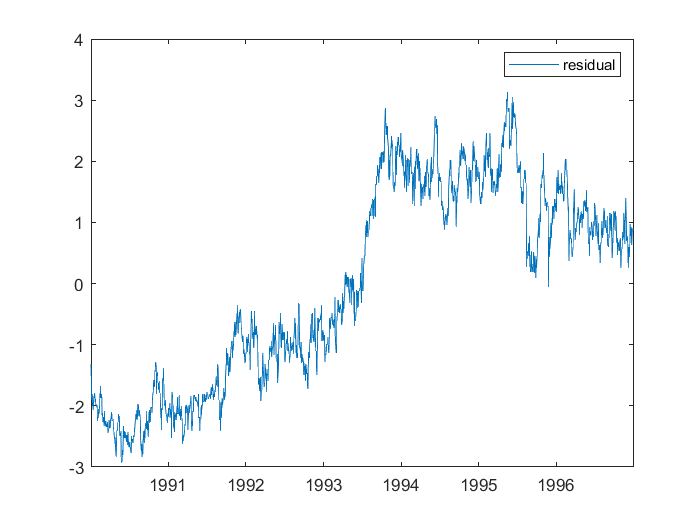

pxDifference = series(:,1)-(series(:,2)*reg0.coeff(2)+reg0.coeff(1));
plot(SPX218{:,1}, pxDifference)
legend("residual");

clear selectedPairs

numPairs = 20;
selectedPairs = coStocks(outliers + 1:numPairs + outliers, 2:5);

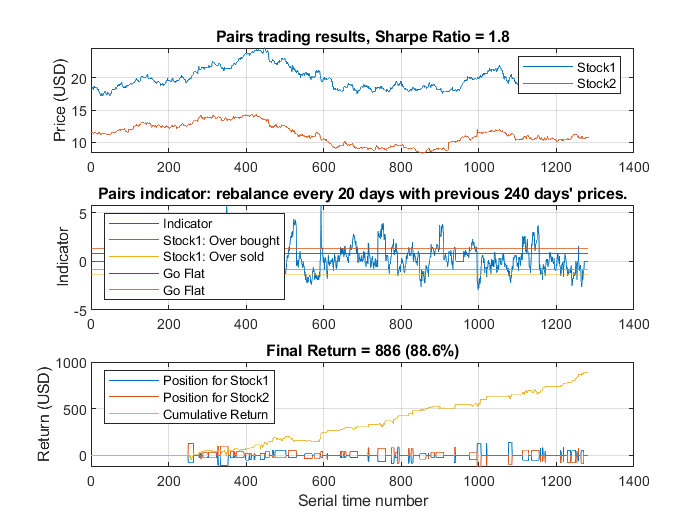

a1 =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


a2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


a3 = 1.7988

a4 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percentReturn =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


result0 = 	1.0e+03 *

    0.0162    0.0100         0         0         0         0         0         0         0         0         0    1.0000
    0.0160    0.0100         0         0         0         0         0         0         0         0         0    1.0000
    0.0157    0.0099         0         0         0         0         0         0         0         0         0    1.0000
    0.0155    0.0098         0         0         0         0         0         0         0         0         0    1.0000
    0.0154    0.0097         0         0         0         0         0         0         0         0         0    1.0000
    0.0153    0.0098         0         0         0         0         0         0         0         0         0    1.0000
    0.0153    0.0097         0         0         0         0         0         0         0         0         0    1.0000
    0.0153    0.0098         0         0         0         0         0         0         0         0         0    1.0000
    0.0151

clf
tic
% For in-sample set
[a1,a2,a3,a4,percentReturn,result0]=pairsNew(SPX218, selectedPairs)

% For out-of-sample set
% [a1,a2,a3,a4,percentReturn,result0]=pairsNew(SPX218, selectedPairs,240,20,1.3,0.8,sqrt(252),0.01,0)
toc

Elapsed time is 24.444084 seconds.


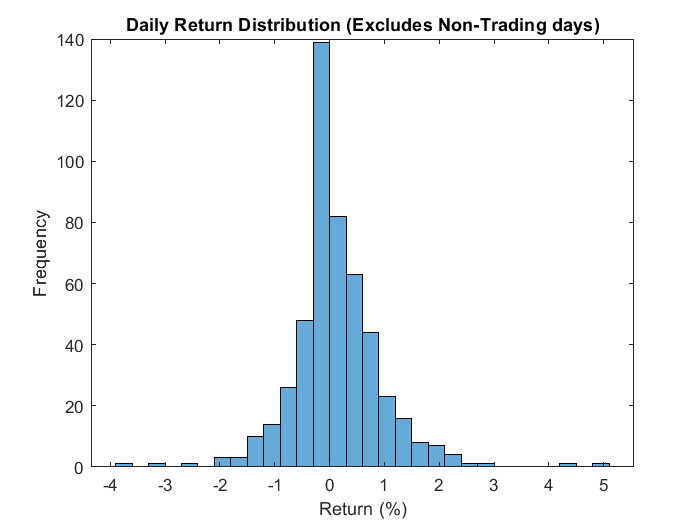

clf
histogram(percentReturn(percentReturn~=0)*100)
title('Daily Return Distribution (Excludes Non-Trading days)');
ylabel('Frequency');
xlabel('Return (%)');

% Comment out the optimization procedure below when using out-of-sample set
p = gcp('nocreate');
if isempty(p)
    p = parpool('local');
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).



window = 120:60:420;
freq   = 10:10:60;
range = {window, freq};

spreadH = 1.3;
spreadL = 0.8;

annualScaling = sqrt(252);
cost = 0.01;

pfun = @(x) pairsFunNew(x, SPX218, selectedPairs, spreadH, spreadL, annualScaling, cost);

tic
[~,param] = parameterSweep(pfun,range);
toc

Elapsed time is 266.199364 seconds.


pairsNew(SPX218, selectedPairs, param(1), param(2), spreadH, spreadL, annualScaling, cost)

save Insample.mat
% save Outsample.mat